rng(0);
clear;

Consider the dataset provided within the folder “data_fruit” For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. Each datum is an image of size 80 × 80 pixels with 3 color channels red (R), green (G), and blue (B), i.e., a 80 × 80 × 3 array. For PCA, each image should be resized to a vector of length 19200. For visualization, reshape each vector back to a RGB image of size 80 × 80 pixels using the function reshape(), followed by a shift and rescaling of the values into the range [0, 1], followed by displaying the matrix using the function image(). 

imgs = readall(imageDatastore('data_fruit/*.png'));
[imgsz,~] = size(imgs);

for i = 1:imgsz
    imgs{i} = double(reshape(imgs{i}, 19200, 1))/255; 
    
end


• (9 points: 1 + 4 + 4) Similar to the analysis done in previous question, find the mean µ, the covariance matrix C, and the top 4 principle eigenvectors of C. Display the mean and the eigenvectors as images (side by side, in the same figure); you can use the function subplot(). Find the top 10 eigenvalues, sort them, and plot their values on a graph. Use the function eigs() for efficient computation. 

mu = 0; %mean
C = 0; %covariance
for i = 1:imgsz
    mu = mu + imgs{i};
    C = C + (imgs{i}-mu)*((imgs{i}-mu)');
end
mu = mu/imgsz;
C = C/(imgsz-1);
mu

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


C

C =    21.0526   21.5618   21.7684   21.1343   21.4577   22.0065   21.9022   21.8942   22.2573   22.6999   23.1509   23.2013   22.6861   22.5606   22.5705   23.3022   23.1009   23.0674   22.3556   20.6187   19.2474   17.8531   17.9976   18.3145   19.1316   19.8934   20.4932   21.7075   22.7914   23.2526   23.3105   23.2856   23.2846   23.4020   23.3935   23.1653   23.0740   23.0673   22.6289   22.3045   21.8445   21.5213   20.9861   20.6724   19.8965   19.2557   18.9890   18.9296   18.5894   18.1551
   21.5618   22.0837   22.2952   21.6450   21.9763   22.5388   22.4320   22.4238   22.7960   23.2493   23.7112   23.7630   23.2354   23.1070   23.1164   23.8661   23.6592   23.6248   22.8951   21.1154   19.7112   18.2822   18.4299   18.7525   19.5885   20.3693   20.9836   22.2277   23.3387   23.8117   23.8713   23.8458   23.8453   23.9662   23.9573   23.7232   23.6298   23.6231   23.1745   22.8421   22.3709   22.0404   21.4925   21.1716   20.3780   19.7217   19.4489   19.3885   19.0402   18

[Q, D] = eigs(C, 10); % eigs(C, k) gets the k largest eigenvals and corresponding eigenvectors
D = diag(D);    %top 10 eigenvals
D

D = 1.0e+05 *

    3.4544
    0.0072
    0.0024
    0.0013
    0.0008
    0.0004
    0.0004
    0.0003
    0.0002
    0.0001



Q = Q(:, 1:4)   %only first 4 eigenvecs

Q =    -0.0078   -0.0131    0.0204   -0.0007
   -0.0079   -0.0138    0.0204   -0.0011
   -0.0080   -0.0135    0.0204   -0.0011
   -0.0078   -0.0118    0.0211   -0.0008
   -0.0079   -0.0121    0.0213   -0.0005
   -0.0081   -0.0129    0.0204   -0.0001
   -0.0081   -0.0132    0.0190    0.0002
   -0.0081   -0.0132    0.0189   -0.0001
   -0.0082   -0.0137    0.0192   -0.0002
   -0.0084   -0.0130    0.0190   -0.0021


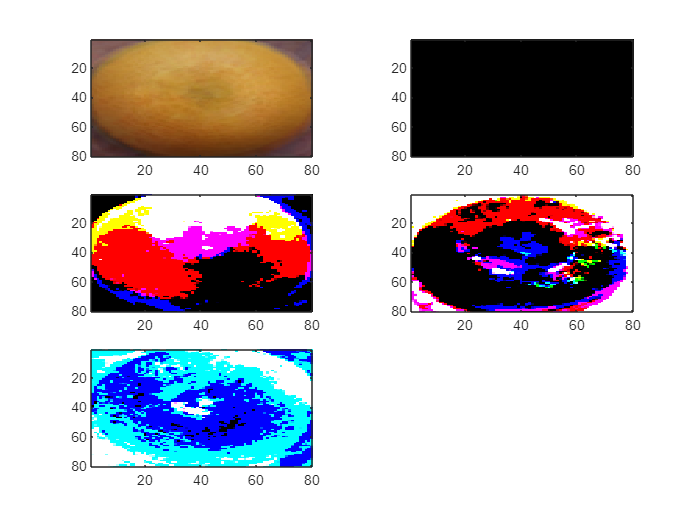

figure
t = tiledlayout(1, 5);
axis equal;
nexttile
imagesc(reshape(mu, 80, 80, 3))

%imagesc(reshape(Q(:, 1) + mu, 80, 80, 3))
for i = 1:4
    nexttile
    imagesc(reshape((Q(:, i)*sqrt(D(i)))*255, 80, 80, 3))    
end


hold off

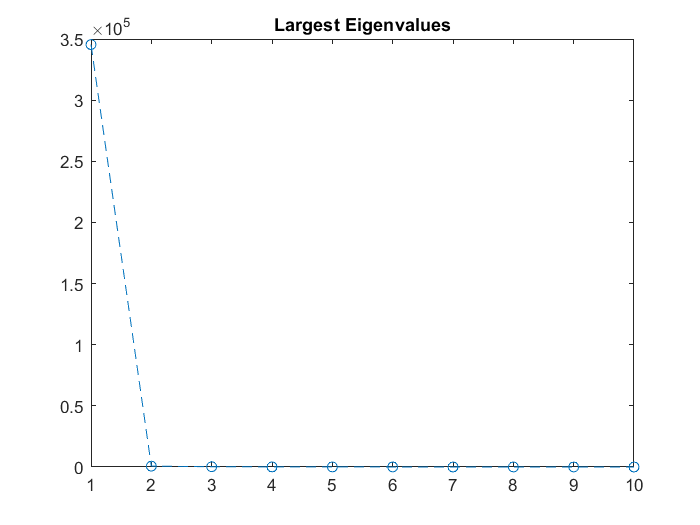


figure
plot(1:10, D,'o--');
title("Largest Eigenvalues");

• (8 points: 4 + 4) For each fruit image in the dataset, finds its closest representation as a linear combination of the top 4 eigenvectors added to the mean. Use the measure of closeness as the Frobenius norm of the difference. Describe the algorithm used to produce this closest representation in mathematical terms and describe the logic behind your algorithm. Display the original fruit image and its closest representation, as images (side by side, in the same figure). 

Observe that each fruit image is a vector with 19200 dimensions. Since the convariance matrix is symmetric, from the **Spectral Theorem**, we know that it has 19200 orthogonlaeigenvectors

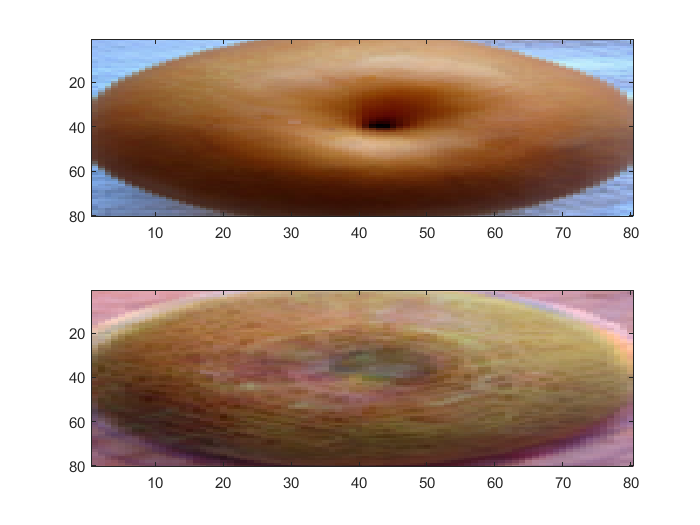

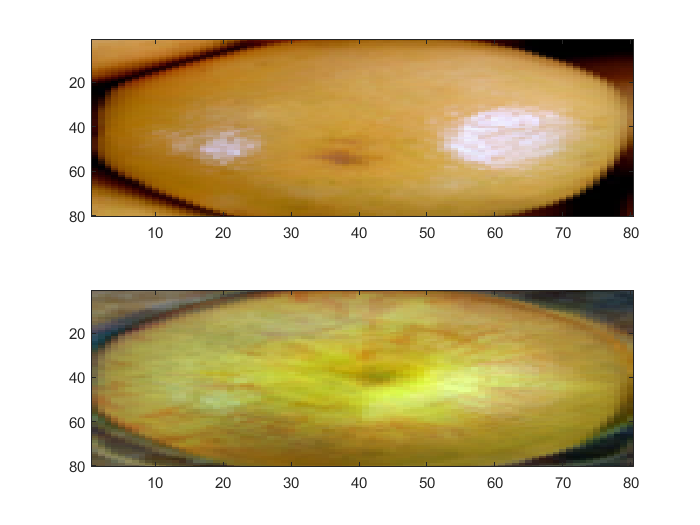

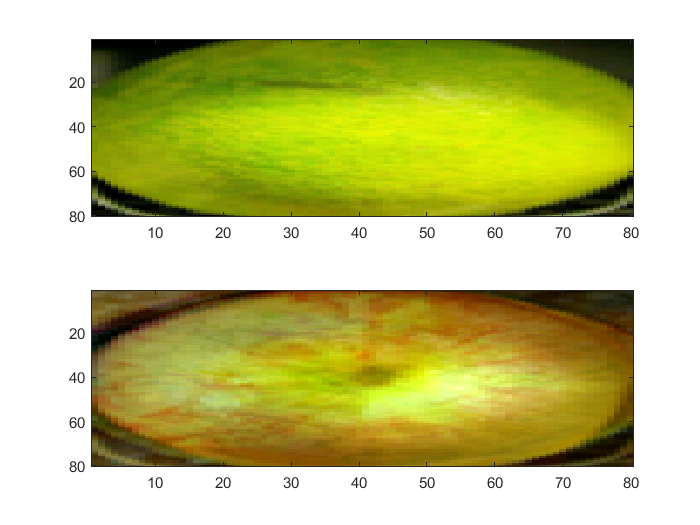

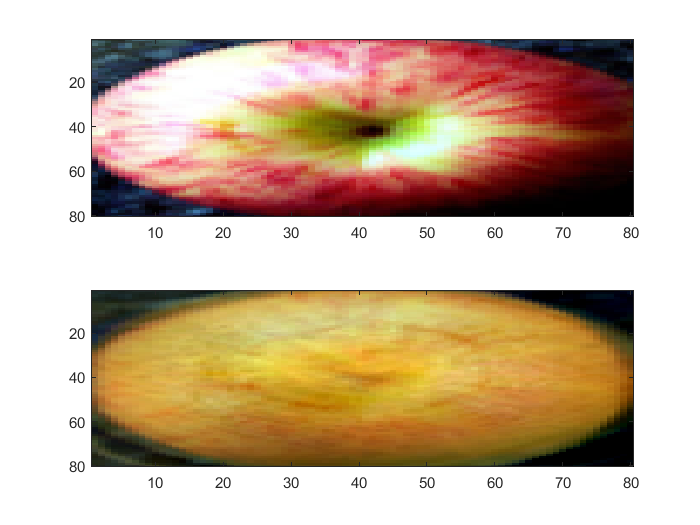

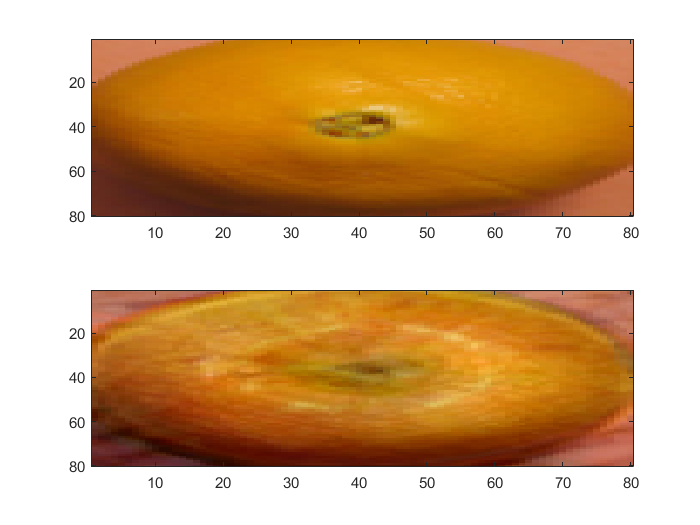

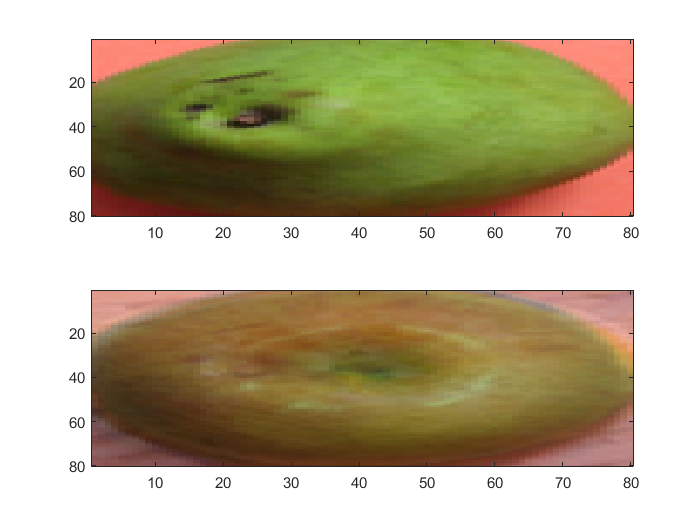

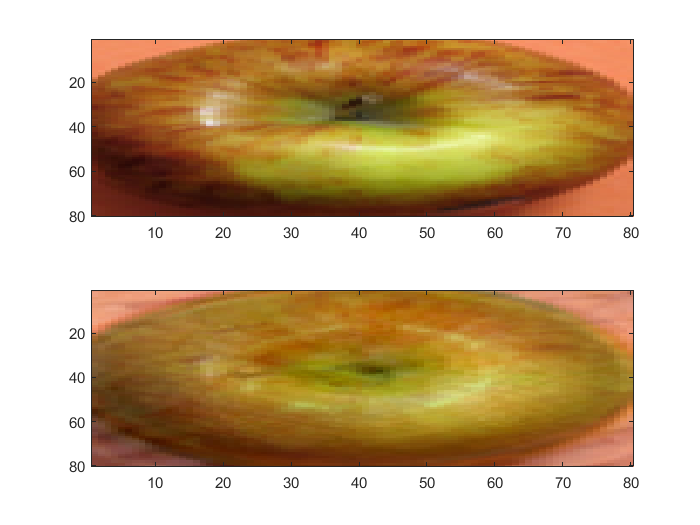

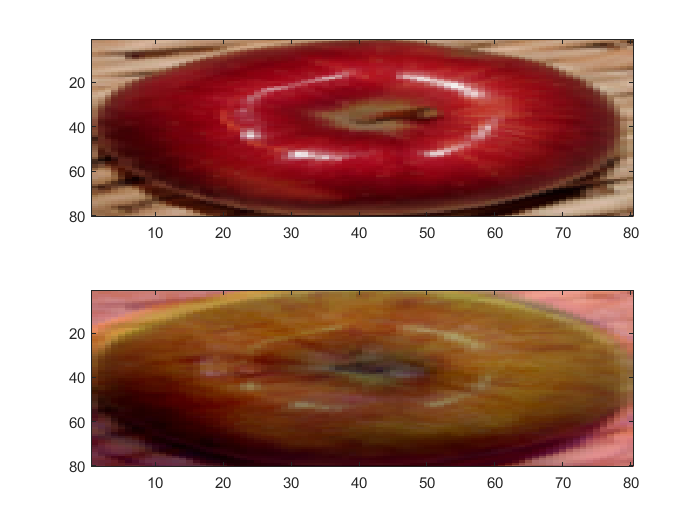

for i = 1:imgsz
    pause(0.01)
    figure
    temp_img = imgs{i} - mu;
    components = (temp_img')*Q;
    close_rep_mat = mu + (sum(components*Q', 1))';
    t = tiledlayout(1, 2);
    axis equal;
    nexttile
    imagesc(reshape(imgs{i}, 80, 80, 3));
    hold on
    nexttile
    imagesc(reshape(close_rep_mat, 80, 80, 3));
    pause(0.01)
end

• (9 points: 3 + 3 + 3) Using all of the top 4 eigenvectors and the mean image, sample random images to generate new images of "fruit". Describe the underlying algorithm clearly in words and including suitable mathematical notation. Display three such images that are distinct from any image in the given the dataset, but are representative of the dataset and can be considered as that of a new / generated fruit.